# Introduction to neural networks: logistic regression classifier

## What are neural networks?

**Neural networks** are a set of algorithms that are inspired by neural circuits in the brain. These algorithms can be computationally intensive, and have recently exploded in popularity due to advances in computing technology, such as GPUs that can perform computations in parallel with the CPU. 

Neural networks generally work by taking linear combinations of predictors in the input dataset to engineer new representations of our features. Non-linear functions are applied to the new feature. This is repeated several times until we get an output that best represents the response variables in the output dataset. This family of learning methods are really flexible, and can be used for classification and regression problems.                                                                                                                         

### Modern applications of neural networks

Neural networks have been applied to several real-world problems, from[ determining medical diagnoses by classifying images](https://towardsdatascience.com/medical-diagnosis-with-a-convolutional-neural-network-ab0b6b455a20) to [training a self driving car](https://towardsdatascience.com/deep-learning-for-self-driving-cars-7f198ef4cfa2) to [biomedical text mining for extracting relevant patient information](https://medium.com/@Petuum/applying-neural-networks-to-biomedical-text-mining-fe655270c12). The main advantages of neural networks are the following:

- They are highly non-linear models that can detect nonlinear relationships and interactions between predictors/response variables

- The mathematics underpinning neural networks relies less on statistical assuptions we usually impose in other models

- Neural networks are modular, and many architectures are available to model different problems

### Common components and notation of a neural network

There are [several flavors of neural network architectures](https://medium.com/cracking-the-data-science-interview/a-gentle-introduction-to-neural-networks-for-machine-learning-d5f3f8987786), each one having their own advantages and disadvantages for solving different problems. The diagram below illustrates a **feed-forward neural network**, where information flows forward from the input to the output, and no information feeds back into the network. 

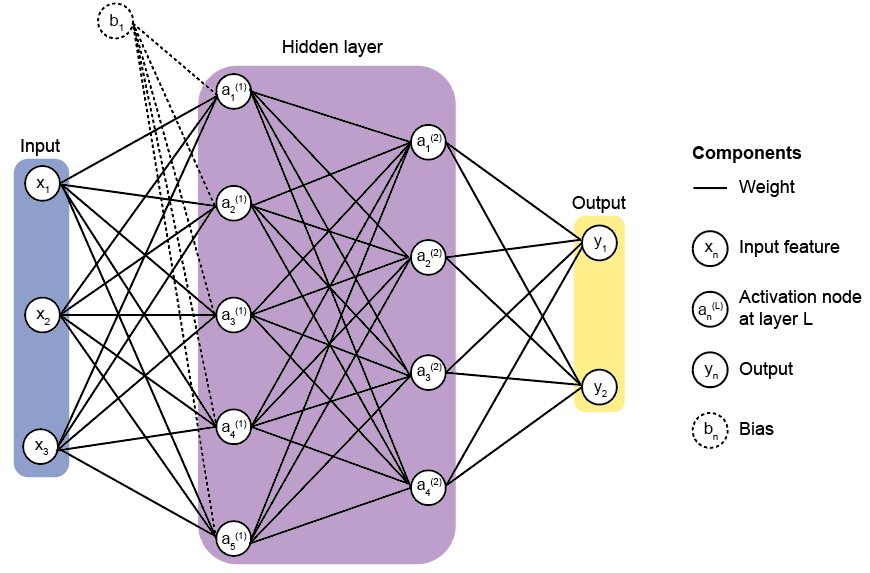

#### The input layer

Each node in the **input layer** represents a feature in the training data ($X_{\textrm{train}}$). Each edge corresponds to a **weight** vector. Further, we can choose to add more flexibility into the model by introducing some **bias** values. When we compute values that are propagated to the activation node, we'll be solving equations that are analagous to the linear regression expression, where we will solve equations that look like $Z\;=\;X\cdot \textrm{weights}+\textrm{bias}$.

#### The hidden layer(s)

The hidden layer is where the new values are stored from taking linear combinations of features from the input layer and applying non-linear transformations. These nodes are are known as **activation nodes**, and each activation node in the hidden layer represents a single new feature. 

A neural network with a single hidden layer is known as a **shallow neural network**. However, we can add more complexity in the model by adding more hidden layers and more activation nodes. Neural networks with more than 1 hidden layer are known as **deep neural networks** (DNNs), and the application of DNNs is known as **deep learning**. 

#### **The output layer**

From the last hidden layer, the final values are propagated to the **output layer**. In this layer, we can use rules to turn these values into labels for a classification problem, or keep the probabilities in a regression problem. 

**To illustrate the main concepts underpinning neural networks, we'll code up a shallow feedforward neural network from scratch.** There are three main phases in a feedforward neural network that we'll go over in depth:

- Fitting the model in **forward propagation**

- Evaluating the performance of the trained model using a **cost function**

- Tuning model parameters using **backward propagation and gradient descent**

## Step 1: Constructing new features using forward propagation

The training phase of a neural network is called [forward propagation](https://towardsdatascience.com/forward-propagation-in-neural-networks-simplified-math-and-code-version-bbcfef6f9250)**. **It consists of iteratively computing linear combinations of the input fed into each layer, followed by a non-linear transformation of the combined features. This is repeated for each hidden layer until we reach the output layer.

### Computing linear combinations of features 

Let's first use an artificial dataset to demonstrate what forward propagation does to our data. The example below uses a training dataset $X$ with 20 observations and 3 predictor variables.  

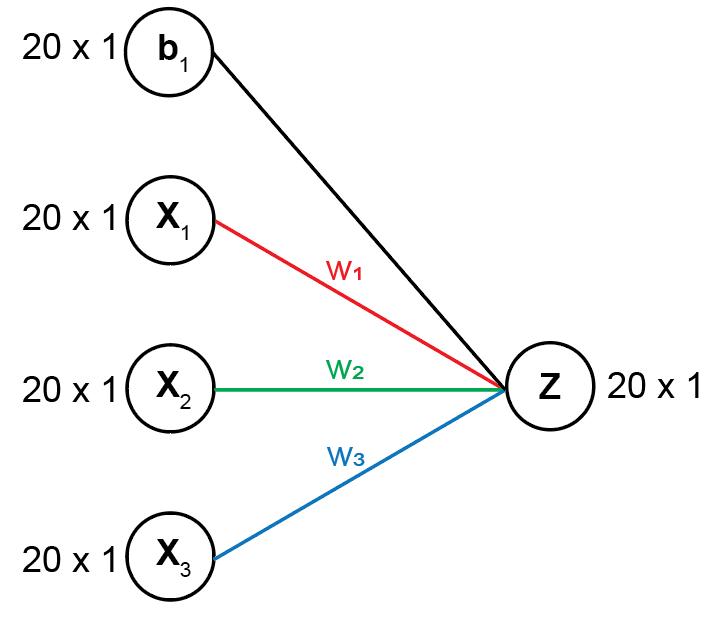

The formula to take a linear combination of predictors has the same structure as the linear regression equation:


$$Z=Xw^T +b$$


Our problem in this step is slightly different from a linear regression problem in that we are solving for the output $Z$ rather than using $X$ and $Z$ to estimate our coefficients. However, we have the same global objective of trying to estimate the two parameters of interest, which we do in later steps: 

- The **weights** ($w$), which is equivalent to the regression coefficients $\beta$

- The **bias** ($b$) values, which is equivalent to the intercept $\beta_0$. 

#### Impact of weights on the new feature `Z` generated by the neural network 

We'll see how the two parameters $w$ and $b$ affect the solution $Z$, and then plot the relationship between $X$ and $Z$. We'll take linear combinations with 1 to 3 weights of different values. 

% Set a fixed random number generator (rng) for reproducibility
rng(2);
X = normrnd(0, 1, [20, 3])
b = randn([20, 1])

#### Solution using 1 weight value

The following network diagram using 1 weight value is shown below:

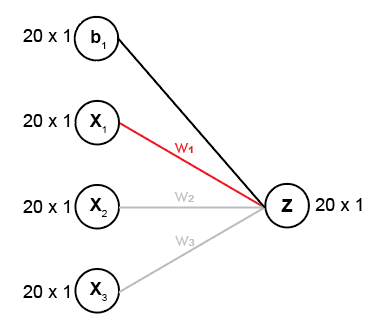

Which is equivalent to solving the following equation: $Z=X_1 w_1 +b$

% Weight vectors
w = [1, 0, 0]; % Only 1 weight
Z1 = X * w' + b

Let's now plot the relationship between each feature in $X$ and the output $Z$. 

figure; gray = [200, 200, 200] / 255; 
subplot(1, 3, 1); scatter(X(:, 1), Z1, 'red', 'filled')
xlabel('X_{1}');  ylabel('Z'); set(lsline, 'color', 'r')
subplot(1, 3, 2); scatter(X(:, 2), Z1, [], gray, 'filled')
xlabel('X_{2}');  lsline
subplot(1, 3, 3); scatter(X(:, 3), Z1, [], gray, 'filled')
xlabel('X_{3}');  lsline

Note that the slight positive relationship between $X_2$ or $X_3$ and $Z$ is not meaningful, but is an artifact from the small number of observations we used to make $X$ and random chance.

#### Solution using 2 weight values

If we include two weights, the network will look like the following diagram:

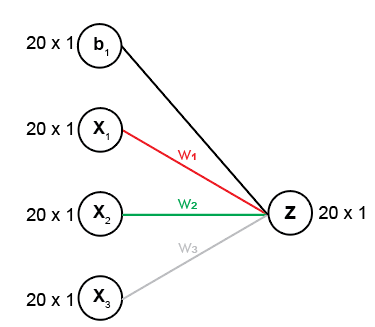

And the equation will look like the following: $Z=X_1 w_1 +X_2 w_2 +b$

You will notice that there is a stronger correlation between the new feature $Z$ and $X_2$, as it is assigned a higher weight.

% Compute Z = x1w1 + x2w2 + x3w3 + b
w = [1, 2, 0]; % 2 weights only
Z2 = X * w' + b
% Make plot
figure; green = [34, 139, 34] ./ 255;
subplot(1, 3, 1); scatter(X(:, 1), Z2, 'red', 'filled')
xlabel('X_{1}');  ylabel('Z'); set(lsline, 'color', 'r')
subplot(1, 3, 2); scatter(X(:, 2), Z2, [], green, 'filled')
xlabel('X_{2}');  set(lsline, 'color', green)
subplot(1, 3, 3); scatter(X(:, 3), Z2, [], gray, 'filled')
xlabel('X_{3}');  lsline

#### Solution using 3 weight values

Finally, let's include a fully connected hidden layer with all 3 weights.

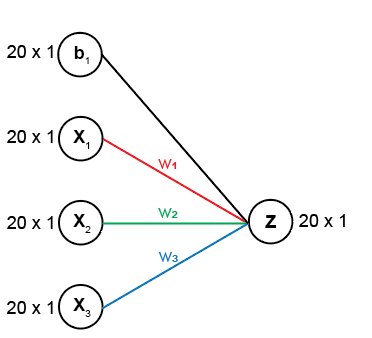

Where the complete equation will look like the following: $Z=X_1 w_1 +X_2 w_2 +X_3 w_3 +b$

% Compute Z = x1w1 + x2w2 + x3w3 + b
w = [1; 2; -5]; % All 3 weights
Z3 = X * w + b
% Make plot
figure; blue = [30, 144, 255] ./ 255;
subplot(1, 3, 1); scatter(X(:, 1), Z3, 'red', 'filled')
xlabel('X_{1}');  ylabel('Z'); set(lsline, 'color', 'r')
subplot(1, 3, 2); scatter(X(:, 2), Z3, [], green, 'filled')
xlabel('X_{2}');  set(lsline, 'color', green)
subplot(1, 3, 3); scatter(X(:, 3), Z3, [], blue, 'filled')
xlabel('X_{3}');  set(lsline, 'color', blue)

We have a new complex feature that is positively correlated with $X_1$ and $X_2$, but negatively correlated with $X_3$,

#### Takeaways

The weights strongly describe the relationship between $X$ and $Z$, and are a really important parameter to learn and tune in the model.

#### How do we initialize the weights and biases in practice?

Without knowing the true relationship between the predictor and response variables, we need to initialize the weight and bias parameters somehow. It turns out that[ intializing neural networks with small and random values for w and b is a better way](https://machinelearningmastery.com/why-initialize-a-neural-network-with-random-weights/) to train these parameters than setting them to all zero or one. We'll explore this idea further later in the lecture.

### Non-linear transformations using an activation function

In this section, we'll discuss different ways to add non-linearity into the computed variable `Z`, and the advantages / disadvantages of each method.

#### The sigmoid activation function

One way to transform the data is to use the sigmoid activation function (aka logit transformation) to transform our data into probabilities with values ranging from [0, 1]. The formulation of the sigmoid activation function is:


$$\textrm{sigmoid}\left(Z\right)=A=\frac{1}{1+e^{-Z} }$$


The shape of the sigmoid distribution is shown below. 

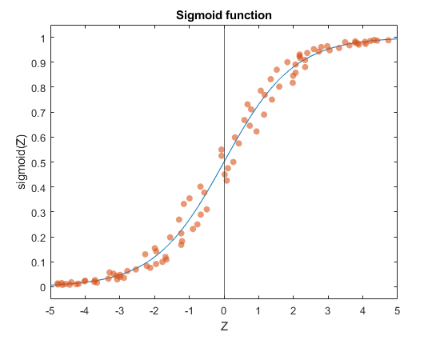

To access all the activation functions described in this lecture, we can use the `activationFnc` script provided in the project folder (documentation described below) to transform our values.

**Applying the sigmoid activation function to **`Z`

Let's see what happens when we apply the sigmoid activation function element-wise to the three Z vectors we computed in the previous section from introducing different weights.

% Compute y using the Z1 cell array containing the results from using different w values
Z = [Z1, Z2, Z3]                % Store all Z values in single array to perform 1 computation
A = activationFnc(Z, 'Sigmoid') % Scaled from 0 -> 1 using sigmoid activation function
% Plot 3 sigmoid curves
figure;
for i = 1:size(A, 2) % Make scatter plot of the sigmoid curves
    subplot(1, 3, i)
    scatter(Z(:, i), A(:, i), ... 
            'filled', 'o', 'MarkerFaceAlpha', 0.6, ... 
            'jitter', 'on', 'jitterAmount', 0.5);       
    xlabel(strcat('Z', string(i))); ylabel(strcat('sigmoid(Z', string(i), ')'));
    ylim([-0.05, 1.05]); xlim([-10, 10]);
end

Applying the sigmoid activation function transforms each $Z$ vector to probabilities scaled from $\left\lbrack 0,1\right\rbrack$. Additionally, the more weights we add, the more nonlinear the data becomes after each sigmoid transformation, shown by the increasingly pronounced sigmoid curves. This feature of the sigmoid activation function is especially useful for binary classification.

### Rectified linear units (ReLUs) 

While the `Sigmoid` activation function is easy to interpret and is simple to apply, there are issues with using it as an activation function:

- With each iteration, the $e^{-Z}$ term in the `sigmoid` function becomes infinitesimally small. When correcting our parameters in back propagation (covered in the next section), correcting these extremely small values result in slower updates. This is called the **vanishing gradient problem**, and is an issue when it comes to optimizing neural network parameters using gradient descent.

- Further, our values are between 0 and 1. This is not really useful for regression problems.

Thus, people have been turning to the ReLU as the preferred activation function, especially for more complex neural network architectures. The formulation of the **ReLU** is shown below, and is really simple:


$$\textrm{ReLU}\left(z\right)=\left\lbrace \begin{array}{cc}
z & \textrm{if}\;z>0\\
0 & \textrm{if}\;z\le 0
\end{array}\right.$$


This basically sets negative values to 0, while leaving the original transformed value intact. The ReLU activation function has the following non-linear distribution shape:

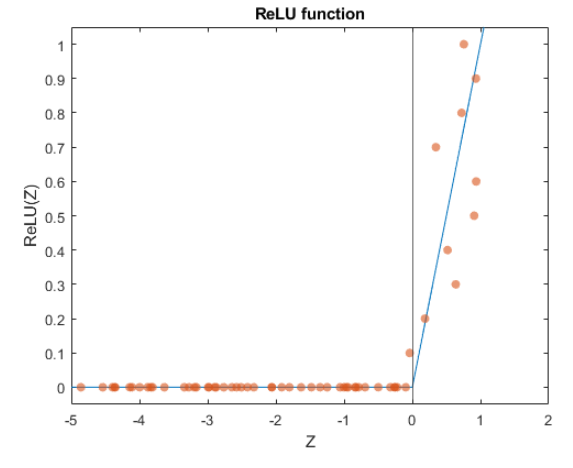

The ReLU has gained popularity in recent years because it takes care of the problems faced by the Sigmoid activation function, such as:

- The correction term in back propagation is not infinitesimally small. This rectifies the vanishing gradient problem.

- Because only a few neurons would be activated (negative values are all 0), this makes the model more efficient.

### Leaky rectified linear units (Leaky ReLUs) 

The ReLU does have its own set of problems, such as handling real negative values (since they're set to 0, the model will essentially ignore these values). 

There is an improved method of the ReLU: the** leaky ReLU**! Instead of setting to value to 0 for negative numbers, we'll scale the negative values using a small weight (usually this weight, which we'll denote as epsilon ($\varepsilon$) is set to 0.01). This will cause a smaller gradient to flow for the negative values, and thus improves our performance with negative numbers.

The formulation for the leaky ReLU is


$$\textrm{Leaky}\;\textrm{ReLU}\left(Z\right)=\left\lbrace \begin{array}{cc}
z & \textrm{if}\;z\;\textrm{is}\;\textrm{positive}\\
\varepsilon \cdot z & \textrm{if}\;z\;\textrm{is}\;\textrm{negative}
\end{array}\right.$$


The leaky ReLU has the following distribution shape:

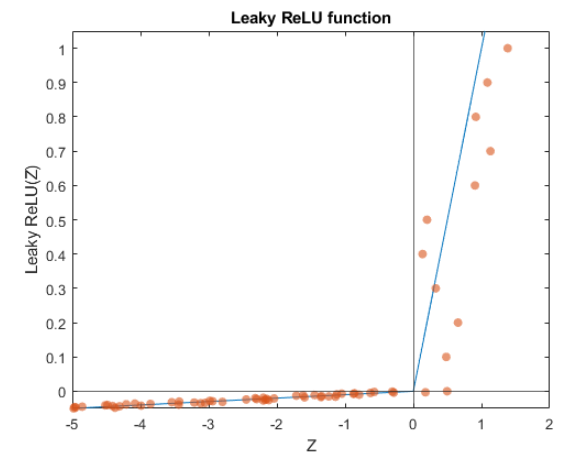

Now that we have covered a single round of combing features and adding non-linearity to the combined features, we have the tools to run a full round of forward propagation. 

### A single round of forward propagation

Let's now put all of these concepts together to run 1 round of forward propagation with **no hidden layer** using a breast cancer dataset built into MATLAB. Without the hidden layer, we're training a model that is essentially a logistic regression model.  

#### Description of breast cancer dataset

The dataset can be called using the `load cancer_dataset `command, and a comprehensive description of the dataset can be found by typing in `help cancer_dataset`. 

- The input is a matrix of 9 features from 699 biopsies. The features include attributes such as adhesion, cell size, and cell shape. These are stored in the `cancerInputs` variable. 

- The `cancerTargets` variable is a 2 x 699 matrix, where the first row corresponds to benign, and the the second row corresponds to malignant. Thus, we will perform binary classification.

clear all;
load cancer_dataset.mat

% View input dataset. Rows = features. Columns = observations
data = array2table(cancerInputs, ...
    "RowNames", {'Clump thickness', 'Uniform Cell size', ...
    'Uniform Cell shape', 'Adhesion', 'Single cell size', ...
    'Bare nuclei', 'Bland chromatin', 'Normal nucleoli', ...
    'Mitoses'})
% View target dataset. Rows = targets. Columns = observations
target = array2table(cancerTargets, ...
    "RowNames", {'Benign', 'Malignant'})

The model schematic and an overview of the computations we will be performing is shown below. 

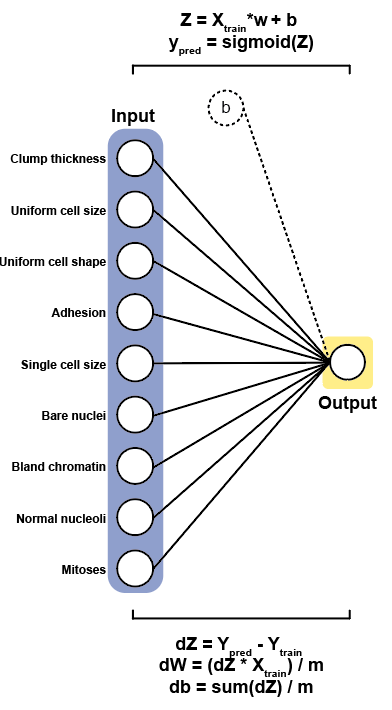

Let's now create the variables we'll need to train and test the model:

% Set seed for reproducibility
rng(2);

% Initialize params for trainTestSplit
trainingSize = 0.8; randomstate = 2;

% Split the dataset into training and test sets.
[Xtrain, Ytrain, Xtest, Ytest] = ...
    trainTestSplit(cancerInputs', cancerTargets(1, :)', ...
    trainingSize, randomstate);

% Standardize the dataset with mean = 0 and standard deviation = 1. 
mu = mean(Xtrain); sigma = std(Xtrain);
Xtrain = (Xtrain - mu) ./ sigma; 
Xtest  = (Xtest - mu)  ./ sigma; % Use the same mu and sigma -> assume same distribution

#### Intialize variables needed to run forward propagation

Our objective is to compute 1 output vector for the binary classification problem. Further, we're going to use the sigmoid activation function, which is essentially equivalent to performing logistic regression.

% Intialize the hyperparameters 
numberOutputNodes = 1; % We are storing the malignant classification vector as a single column 
actFnc = 'Sigmoid'; 

% Intialize the weights and biases. w size should be number of features x number of activation nodes
% for the dot product to work.
w = randn([size(Xtrain, 2), numberOutputNodes])
% b size should be number of observations in training data x 1
b = randn([size(Xtrain, 1), 1])

#### Forward propagation

Let's now run forward propagation from the input layer to the output layer:


$$Z=Xw+b$$


Z = Xtrain * w + b 


$$\textrm{sigmoid}\left(Z\right)=A=\frac{1}{1+e^{-Z} }$$


ypred = activationFnc(Z, actFnc)

Now we need to now see how well our model performed using a cost function.

## Step 2: Evaluating the model fit using the cost function

Next, we need to evaluate how well our model has performed in it's initial pass through using a cost function. Because we are performing a binary classification problem, we can use the **cross-entropy cost function**, which estimates the error of the two classes**.**

### **Cross-entropy cost function**

Recall the formulation for the Cross-Entropy cost function:


$$J=-\frac{1}{m}\sum_{i=1}^m \left\lbrack -{y_{\textrm{train}} }^{\left(i\right)} \log \left(y_{\textrm{pred}}^{\left(i\right)} \right)-\left(1-{y_{\textrm{train}} }^{\left(i\right)} \right)\log \left(1-y_{\textrm{pred}}^{\left(i\right)} \right)\right\rbrack$$


where $m$ are number of observations, $y_{\textrm{train}}$ is the response variable, and $y_{\textrm{pred}}$ is a vector of the predicted value from forward propagation. 

The **cost** value (`J)` can be computed using the `costFunction` function provided. The docstring is provided below:

lossFunction = 'Log-Loss'; J = costFunction(Ytrain, ypred, lossFunction)

Now that we have a cost value, we can start to optimize our logistic regression algorithm using backward propagation.

## Step 3: Optimizing `w` and `b` parameters using backward propagation

After computing the cost, we know how good or how bad our model performed overall. In neural networks, we need to tell the algorithm how to adjust the weight and bias parameters so that the cost goes down in the next iteration, until we reach a stable minimum cost value. 

The process of identifying where the errors from our model come from is called **back propagation**, and the optimization algorithm we use to update the weights and the biases is **gradient descent**. 

### Finding the gradients `dW` and `db` using back propagation

The objective of back propagation is to determine how much we should change `w` and `b` such that we minimize the cost. Thus, we need to find an expression that allows us to relate the cost back to the parameter`. `

The **gradient**, or the values from solving partial differential equations of the cost with respect to $W$ ($\frac{\vartheta J}{\vartheta W}$) and $b$ ($\frac{\vartheta J}{\vartheta b}$) will tell us how much error a specific activation node contributes to the overall model error.

#### Intuition for back propagation 

Formulated below are the expressions needed to solve $\frac{\vartheta J}{\vartheta W}$ and  $\frac{\vartheta J}{\vartheta b}$ for each layer:

$\frac{\vartheta J}{\vartheta W}$ = $\frac{\vartheta J}{\vartheta y}\cdot \frac{\vartheta y}{\vartheta Z}\cdot \frac{\vartheta Z}{\vartheta W}$ 

$\frac{\vartheta J}{\vartheta b}$ = $\frac{\vartheta J}{\vartheta y}\cdot \frac{\vartheta y}{\vartheta Z}\cdot \frac{\vartheta Z}{\vartheta b}$ 

Let's consider the gradient $\frac{\vartheta J}{\vartheta W}$ (the same logic applies for $\frac{\vartheta J}{\vartheta b}$) and work backwards from the output layer to the input layer. There are three places where the model can go wrong: 

- From the output layer to the hidden layer ($\frac{\vartheta J}{\vartheta y}$). A natural expression to compute this error is $Y_{\textrm{pred}} -Y_{\textrm{train}}$.

- From the activation function ($\frac{\vartheta y}{\vartheta Z}$) from each hidden layer. This expression changes with different activation functions.

- From computing the new feature $Z$ with the current weight $w$ ($\frac{\vartheta Z}{\vartheta W}$). 

As you can see, each layer is chained together. Fortunately, because we know how the network is connected, we can figure out partial differential terms that will connect the cost to any given weight or bias parameter that needs to be adjusted to lower the cost. 

We won't go over the derivation for each term, but in practice, we would work these differential equations individually and use the chain rule to compute the gradients. 

#### Derivative terms for back propagation in a logistic regression model

The following set of equations are used in our logistic regression model to compute the gradients for each parameter (denoted as `dw` and `db)`. Because we're comparing our predictions directly against our training set, we don't have to compute the error from the activation function.


$$\textrm{dZ}=Y_{\textrm{pred}} -Y_{\textrm{train}} \;$$



$$dW=\textrm{dZ}\cdot {X_{\textrm{train}} }^T \cdot \frac{1}{m}$$



$$\;\textrm{db}=$$
 
$$\frac{1}{m}\sum_{i=1}^n \left(\textrm{dZ}\right)$$


### Back propagation 

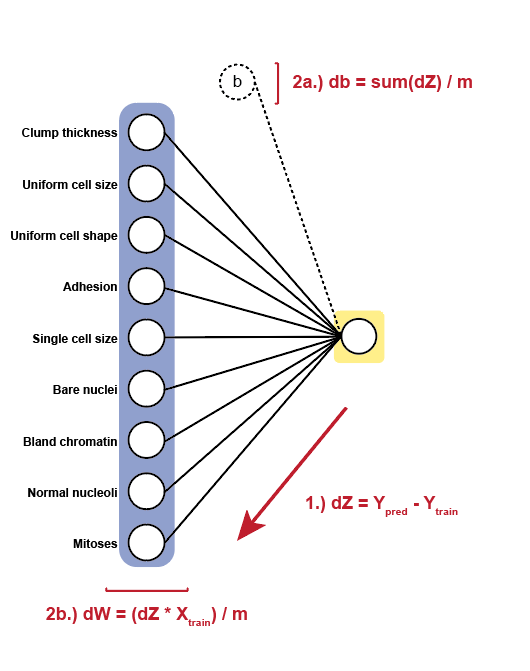

The schematic above is a diagram representing the errors we will be computing from scratch. Now let's codify our back propagation algorithm. First we need to compute the error from the outermost layer: $\textrm{dZ}=Y_{\textrm{pred}} -Y_{\textrm{train}} \;$

dZ = ypred - Ytrain

Next, we have to compute how much error our weights contributed to the overall error in proportion to `dZ.` $\frac{1}{m}$ normalizes our error term by the number of observations in the dataset: $dW=\frac{1}{m}\left(\textrm{dZ}\cdot {X_{\textrm{train}} }^T \right)$

m = size(Xtrain, 1)          % m = number of observations in training set
dW = (1/m) .* (Xtrain' * dZ)

Finally, we compute the error in the bias term, which is the sum of the errors from the output layer normalized based on the number of observations in the data: $\textrm{db}=$ $\frac{1}{m}\sum_{i=1}^n \left(\textrm{dZ}\right)$ 

db  = (1/m) .* sum(dZ, 2)

We have just completed the first iteration of back propagation, which relates the cost value J back to the parameters w and b. The last step we need to do is to update the weights and biases. We'll be using the **gradient descent** optimization algorithm.

### Optimizing parameters `W` and `b` using gradient descent

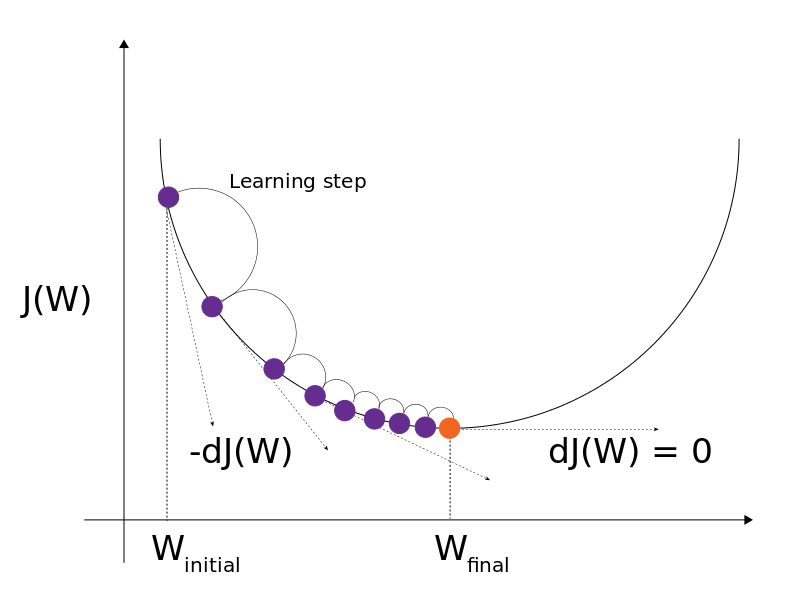

The objective of gradient descent is to minimize the cost by updating the parameters in the model such that it is going against the gradient. The intuition is that by moving away from the gradient, we'll lower the cost value until we reach a gradient that is close to zero. This will suggest to our gradient descent algorithm that we have reached a minimum cost. 

Because we have two parameters **W** and **b**, we have two update equations:


$$\begin{array}{l}
\mathrm{W}=\mathrm{W}-\left(\textrm{learning}\;\textrm{rate}\cdot \textrm{dW}\right)\\
\mathrm{b}\;\;=\mathrm{b}\;\;-\left(\textrm{learning}\;\textrm{rate}\cdot \textrm{db}\right)
\end{array}$$
 

where the learning rate hyperparameter is a positive constant value that controls how fast we move along the gradient. Further, `dW` and `db` are the gradients we computed from back propagation. Because it is a scalar, we will perform element-wise multiplication.

learning_rate = 0.05;
w = w - (learning_rate .* dW)
b = b - (learning_rate .* db)

## Optimizing the logistic regression model using forward and backward propagation

Now that we did a single pass of forward and backward propagation with our logistic regression model, let's make an algorithm that uses forward and backward propagation to optimize the two parameters `w` and `b` after 500 iterations. A common term to express a single iteration of a forward and backward pass through the network is called an **epoch. **

First, let's re-initialize the variables we used in forward propagation, cost computation, and backward propagation:

% Re-intialize variables
epoch = 500; learning_rate = 0.05; numberOfOutputNodes = 1;  % Hyperparameters
m = size(Xtrain, 1);                                         % Normalizing scale
actFnc = 'Sigmoid';                                          % Sigmoid activation function
w = randn([size(Xtrain, 2), numberOfOutputNodes]);           % Number of Xtrain features x number of responses
b = randn([size(Xtrain, 1), 1]);                             % Number of observations

### Logistic regression with forward and backward propagation

Next, we need to write an expression that will allow us to loop all three steps several times, while simultaneously updating the weights and biases after each epoch. To see how the cost changes with each epcoh in real time, we're going to create a progress bar using the `waitbar` function, which shows

wtbr = waitbar(0, '0', 'Name', 'Cost per optimization');

for i = 1:epoch                                     % Iterate forward and backward propagation + gradient descent 500 times
    Z = Xtrain * w + b;                             % 1. Forward propagation
    ypred = activationFnc(Z, actFnc);
    
    J(i) = costFunction(Ytrain, ypred, 'Log-Loss'); % 2. Cost evaluation -> store the costs for plot
    waitbar(i/epoch, wtbr, sprintf('%f', J(i)))     %    Update the waitbar
    
    dZ = ypred - Ytrain;                            % 3. Back propagation
    dW = (1/m) .* (Xtrain' * dZ); 
    db = (1/m) .* sum(dZ, 2);
     
    w = w - (learning_rate .* dW);                  % Gradient descent for iterative update
    b = b - (learning_rate .* db);
end

### Visualizing the model error from the cost curve

This is how we obtain the final trained model from forward and backward propagation. Note that we saved the cost for both class predictions during our `for` loop. 

Let's now plot the cost curve using the cost values `J` against the number of epochs to see how much the error decreased over each training period:

% Cost curve
figure; plot(1:epoch, J, 'color', 'r');
title('Cost with learning rate = 0.05')
xlabel('Number of epochs'); ylabel('Cost (J)')
saveas(gcf, 'logRegressJCurve.fig')

The cost value of using this logistic regression model with forward and backward propagation begins to approach a minimum value around 500 epochs, and has the shape of the **negative binomial distribution**, which is expected from logistic regression. 

### Label encoding for classification

Now that we have our probabilities, we can evaluate the model's performance. But first, we need to turn these probabilities into labels. This process is known as **label encoding**. 

The method shown below has used a probability of 50% (p = 0.5) as the decision boundary for predicting whether or not the sample is a malignant sample.

% Label encoding for classification
ypred(ypred >= 0.5) = 1; % If the probability is greater than 50%, set it to malignant class 
ypred(ypred < 0.5)  = 0; % Otherwise, set it to benign class

## Logistic regression benchmarking

### Training accuracy

We can compute the binary clasification hold-out accuracy using the **zero-one loss** formulation as the error term:


$$\textrm{Accuracy}=1-\textrm{mean}\left(Y_{\textrm{train}} \;\not= {\;Y}_{\textrm{test}} \right)$$


% Compute training accuracy
train_accuracy = 1 - mean(ypred ~= Ytrain)

### Holdout accuracy

The training accuracy is high, as we would expect. We should also compute the holdout and k-fold cross validation accuracies. 

clear ypred;                      % Remove training predictions
Z = Xtest * w;                    % Compute predictions using the test set
ypred = activationFnc(Z, actFnc); % Transform to logit space

% Label encode the predicted values from the test set
ypred(ypred >= 0.5) = 1; % If the probability is greater than 50%, set it to malignant class 
ypred(ypred < 0.5)  = 0; % Otherwise, set it to benign class

#### Confusion matrix of the holdout

To visualize the model's performance, let's plot the confusion matrix of the holdout:

% Create confusion matrix
cm             = confusionmat(Ytest, ypred);
figure; labels = {'Malignant', 'Benign'};
confusionchart(cm, labels);
title('Logistic regression holdout confusion matrix');

#### Model metrics of the holdout

And let's compute other model statistics that we may be interested in:

TP  = cm(1, 1); FP = cm(1, 2); FN = cm(2, 1); TN  = cm(2, 2);
malignant_precision = (TP) / (TP + FP)
malignant_recall    = (TP) / (TP + FN)
benign_precision    = (TN) / (TN + FP)
benign_recall       = (TN) / (TN + FN)
average_accuracy    = sum(diag(cm)) / sum(cm, 'all')

### Cross validation accuracy

The following cross validation schematic shown below was used to compute the cross validation accuracy.

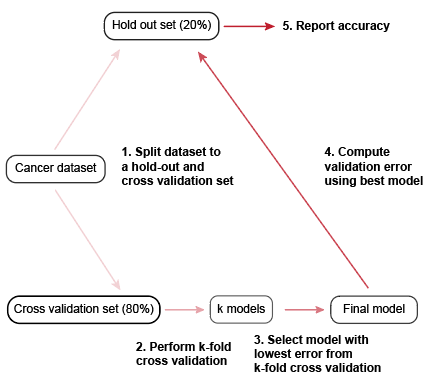

**Why perform cross validation this way?** 

This cross-validation with the holdout ensures that the final model we output never sees the test set. This ensures that we have a really decent estimate of the parameters that is generalizable across several datasets. 

To save space, the procedure described previously has been refactored into the `crossValidate` function. The documentation for the function is shown below:

Let's now run 5-fold cross validation accuracy. We'll compare our results with the shallow neural network later in the section. 

kfold = 5; type = 'Logistic'; hyperparameters = {};

% Run cross validation
logRegressCV = crossValidate(Xtrain, Ytrain, Xtest, Ytest, ...
                            hyperparameters, kfold, type)
save('logisticRegressionResults.mat', 'logRegressCV');

#### Cross validation confusion matrix

figure; labels = {'Malignant', 'Benign'};
cm = logRegressCV.cm;
confusionchart(logRegressCV.cm, labels);
title('Confusion matrix from 5-fold cross validation');
saveas(gcf, 'logRegressCM.fig')
TP  = cm(1, 1); FP = cm(1, 2); FN = cm(2, 1); TN  = cm(2, 2);
malignant_precision = (TP) / (TP + FP)
malignant_recall    = (TP) / (TP + FN)
benign_precision    = (TN) / (TN + FP)
benign_recall       = (TN) / (TN + FN)
average_accuracy    = sum(diag(cm)) / sum(cm, 'all')

## Summary

In this lecture, we went over the three components of a neural network: forward propagation, cost computation, and backward propagation. We then constructed a logistic regression classifier, which is essentially a neural network utilizing the sigmoid activation function without the hidden layer. 

In the next lecture, we'll add the hidden layer to construct the shallow neural network, and discuss how to use neural networks for binary classification, k-class classification, and regression.

### Built-in MATLAB functions

`confusionmat:             `Automatically computes a confusion matrix for each class.

`confusionchart`:                         Plots the confusion matrix from `confusionmat`

### Custom MATLAB functions

`trainTestSplit:           `Splits an input ($X$) and output ($Y$) dataset into a training $\left(X_{\textrm{train}} {,\;Y}_{\textrm{train}} \right)$ and testing $\left(X_{\mathrm{test}} {,\;Y}_{\mathrm{test}} \right)$ dataset

`activationFnc:            `Transforms the dataset using a non-linear function.

`costFunction:`                            Computes the cost value from the model.

`crossValidate:`                          Performs k-fold cross validation.